**Př. 4.:** Z 12 pozorování doby trvání montážní operace byl zjištěn průměr 44 s a směrodatná odchylka 4 s. Sestrojte 90% interval spolehlivosti pro očekávanou délku operace, jestliže daná operace má normální rozdělení.

x_ = 44

x_ = 44

sigma = 4

sigma = 4

n = 12

n = 12

alpha = 0.1

alpha = 0.1000


ci=[x_ - (sigma / sqrt(n)) * tinv(1 - alpha/2, n - 1),...
    x_ + (sigma / sqrt(n)) * tinv(1 - alpha/2, n - 1)]

ci =    41.9263   46.0737


**Př. 5.: **Naměřili jsme 10 údajů o životnosti žárovky: 380, 402, 408, 412, 454, 459, 472, 481, 491, 502 hodin. Odhadněte, zda data jsou z normálního rozdělení (například pravděpodobnostním papírem) a dale určete 95% intervalový odhad střední hodnoty životnosti žárovky. Určete i 95% jednostranný intervalový odhady pro minimální a maximální odhad střední hodnoty. Interpretujte výsledky.

x = [380, 402, 408, 412, 454, 459, 472, 481, 491, 502]

x =    380   402   408   412   454   459   472   481   491   502


[~,~,ci] = ttest(x, mean(x), 0.05)

ci =   415.7623  476.4377


**Př. 6:** V prodejně si udělali průzkum, kolik zákazníků přijde do obchodu během jednoho dne. Byly zjištěny následující data:

x=[541,574,585,596,612,618,632,641,654,671,681,692,711,713,718,719,754,796,812,815,835,858];

Ověřte, že data jsou z normálního rozdělení. Zjistěte 99% interval spolehlivosti odhadu střední hodnoty. 

m = mean(x)

m = 692.1818

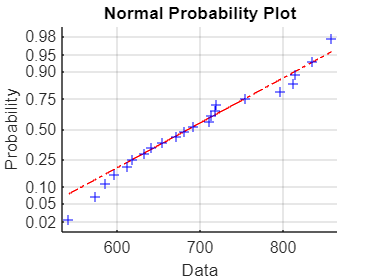

normplot(x)

[~,~,ci] = ttest(x, m, 0.01)

ci =   637.5711  746.7926


**Př. 9.: **Máme naměřená data ve vektoru x. Zjistěte 99% intervalový odhad pro rozptyl a směrodatnou odchylku.

x=[541,574,585,596,612,618,632,641,654,671,681,692,711,713,718,719,754,796,812,815,835,858];

% Odhad rozptylu
[~,~,ci] = vartest(x, var(x), 0.01)

ci = 1.0e+04 *

    0.4151    2.1394


% Odhad směrodatné odchylky
sqrt(ci)

ans =    64.4315  146.2674


**Př. 10.: **Při provádění průzkumu 400 respondentů uvedlo 12 %, že by volilo Stranu mírného pokroku v mezích zákona. Vypočtěte 95% interval spolehlivosti pro očekávanou relativní četnost. Jak se změní interval spolehlivosti, jestliže se budeme ptát 1600 respondentů. 

Zdůvodněte, proč je šířka intervalu u 1600 respondentů poloviční, oproti 400 respondentů. 

alfa = 0.05

alfa =    0.050000000000000


n = 400

n =    400


p = 0.12

p =    0.120000000000000


LB= (p-sqrt(p*(1-p)/n)*norminv(1-alfa/2,0,1)) * 100

LB =    8.815435463578655


PB = (p+sqrt(p*(1-p)/n)*norminv(1-alfa/2,0,1)) * 100

PB =   15.184564536421345



n = 1600

n =         1600


LB= (p-sqrt(p*(1-p)/n)*norminv(1-alfa/2,0,1)) * 100

LB =   10.407717731789328


PB = (p+sqrt(p*(1-p)/n)*norminv(1-alfa/2,0,1)) * 100

PB =   13.592282268210671
